%%%% paper analysis

## Set up path

if(ispc)
    homeFolder = 'C:\Users\Raeed\';
else
    homeFolder = '/home/raeed/';
end
% addpath(genpath('C:\Users\Raeed\Projects\limblab\ClassyDataAnalysis'))
% addpath(genpath('/home/raeed/Projects/limblab/ClassyDataAnalysis'))
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'Hindlimb' filesep 'leg_lib' filesep]))
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'lib' filesep]))
cd([homeFolder 'Dropbox' filesep 'Research' filesep 'cat hindlimb' filesep 'Data' filesep])
% addpath('/home/raeed/Projects/limblab/proc-raeed/MultiWorkspace/lib/')
% cd('/home/raeed/Projects/limblab/data-raeed/MultiWorkspace/SplitWS/Han/20160322/area2/')

clear homeFolder

## load neurons

load('sim_10000neuron_20151011.mat','neurons')

## run hindlimb simulation

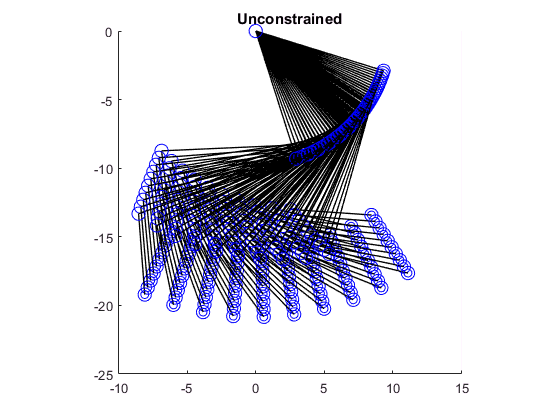

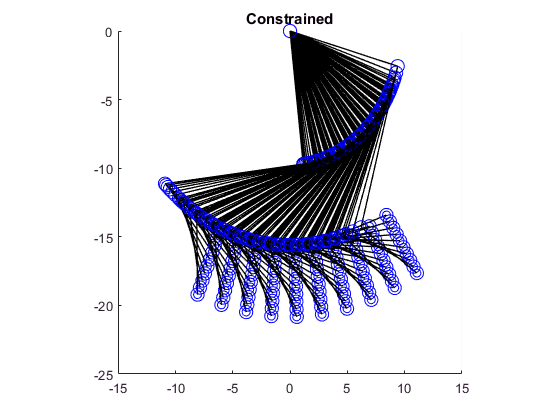

tic
num_sec = 2;
joint_elast = [1;1;1];
[tuning_elast,tuning_fixed,endpoint_positions] = run_hindlimb(neurons,num_sec,joint_elast);

toc

Elapsed time is 241.745967 seconds.


## Extract

is_best_elast = tuning_elast.isTuned;
is_best_fixed = tuning_fixed.isTuned;
isTuned = is_best_elast & is_best_fixed;

coef_elast = tuning_elast.coef(isTuned,:)';
coef_fixed = tuning_fixed.coef(isTuned,:)';

best_act_elast = tuning_elast.activity(isTuned,:);
best_act_fixed = tuning_fixed.activity(isTuned,:);

VAF_elast = tuning_elast.VAF(isTuned,:);
VAF_fixed = tuning_fixed.VAF(isTuned,:);

## Set up for figure gen

base_leg = get_baseleg;
PD_elast = atan2(coef_elast(3,:),coef_elast(2,:));
PD_fixed = atan2(coef_fixed(3,:),coef_fixed(2,:));
moddepth_elast = sqrt(sum(coef_elast(2:3,:).^2));
moddepth_fixed = sqrt(sum(coef_fixed(2:3,:).^2));

## Generate figure 3 - firing rate heat maps

Unit number: 68, Elastic PD: 145.1225, Knee-fixed PD: 115.6755, PD diff: -29.447


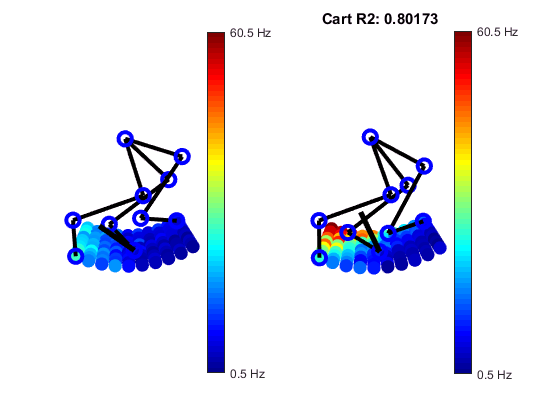

for i = 68
    figure(1234)
    clf
%     subplot(121)
%     plot_heat_map(base_leg,best_act_elast(i,:),endpoint_positions',PD_elast(i),joint_elast)
%     subplot(122)
%     plot_heat_map_con(base_leg,best_act_fixed(i,:),endpoint_positions',PD_fixed(i),joint_elast)
    plot_heat_map_both(base_leg,best_act_elast(i,:),best_act_fixed(i,:),endpoint_positions',PD_elast(i),PD_fixed(i),joint_elast)
    title(['Cart R2: ' num2str(VAF_elast(i))])
    disp(['Unit number: ' num2str(i) ', Elastic PD: ' num2str(PD_elast(i)*180/pi) ', Knee-fixed PD: ' num2str(PD_fixed(i)*180/pi) ', PD diff: ' num2str((PD_fixed(i)-PD_elast(i))*180/pi)])
    
%     waitforbuttonpress
end

## Generate figure 4A - PD distribution

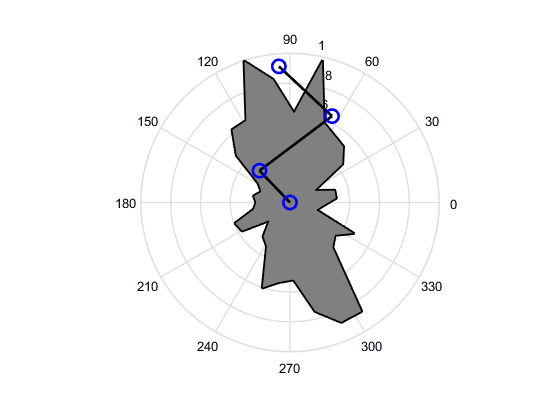

figure
plot_PD_distr(randsample(PD_elast,800,true),36)
hold on

center_ep = mean(endpoint_positions(:,[45 46 55 56]),2);
[~,~,~,segment_angles_unc] = find_kinematics(base_leg,center_ep, 0, joint_elast);
legpts = get_legpts(base_leg,segment_angles_unc);
ep = legpts(:,base_leg.segment_idx(end,end));
hip_rot = legpts(:,base_leg.segment_idx(1,1));

for i = 1:3
    s=base_leg.segment_idx(i,:);
    plot((legpts(1,s)-ep(1))/20, (legpts(2,s)-ep(2))/20, 'k-','LineWidth',2)
    plot((legpts(1,s)-ep(1))/20, (legpts(2,s)-ep(2))/20, 'bo', 'MarkerSize',10, 'LineWidth',2)
end

hold off

## Generate figure 5A - cosdPD histogram

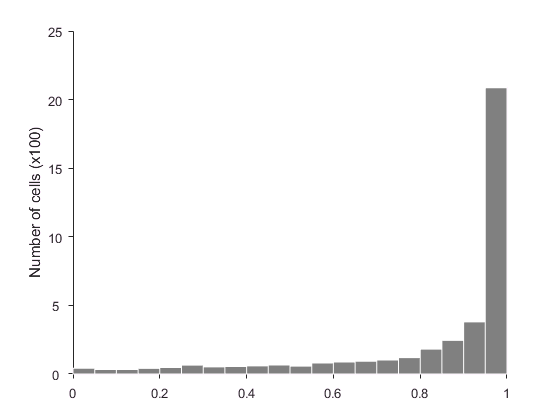

cosdPD = cos(PD_fixed-PD_elast);
figure; hist(cosdPD,40)
set(get(gca,'child'),'EdgeColor','w','FaceColor',[0.5 0.5 0.5])
ylabel('Number of cells (x100)')
yticklabels = get(gca,'yticklabel');
set(gca,'xlim',[0 1],'box','off','tickdir','out','yticklabel',cellfun(@(x) str2double(x)/100,yticklabels),'xtick',0:0.2:1)

## Generate figure 6 - muscle tunings (own script called check_muscle_dir)

Total projected muscle changes: -0.30312, -0.045745
Absolute projected muscle changes: 0.57326, 0.069031
Principal axis elast: 105.2009
Principal axis fixed: 106.9164
Variance accounted for by principal axis (elast): 0.85799
Variance accounted for by principal axis (fixed): 0.87238


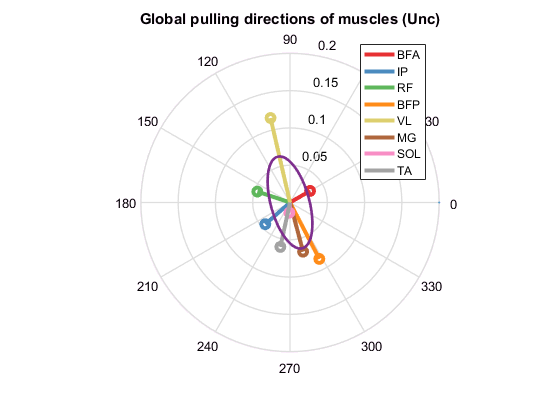

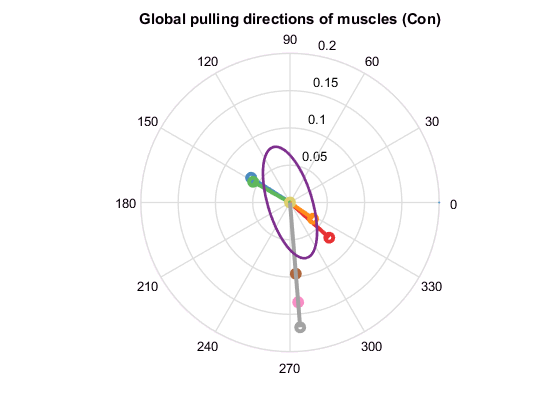

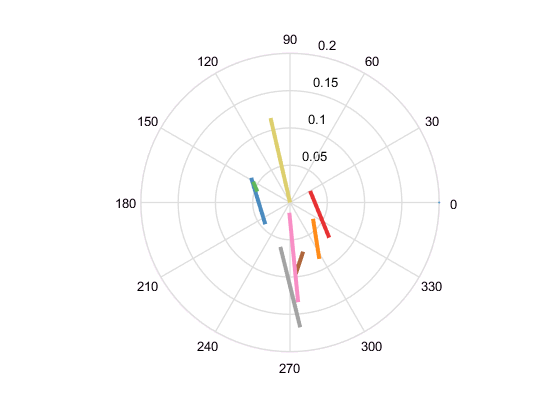

[muscle_coef_elast,muscle_coef_fixed] = check_muscle_dir;

## Generate reported numbers

% percent tuned neurons in each case
disp(['Percent tuned in elastic condition: ' num2str(sum(is_best_elast)/length(neurons)*100)])

Percent tuned in elastic condition: 56.5


disp(['Percent tuned in knee-fixed condition: ' num2str(sum(is_best_fixed)/length(neurons)*100)])

Percent tuned in knee-fixed condition: 64.73


disp(['Percent tuned in both conditions: ' num2str(sum(isTuned)/length(neurons)*100)])

Percent tuned in both conditions: 45.91



% median PD change
disp(['Median cosine \Delta PD: ' num2str(median(cosdPD))])

Median cosine \Delta PD: 0.92262


disp(['Median absolute \Delta PD: ' num2str(acosd(median(cosdPD)))])

Median absolute \Delta PD: 22.6874



% principal axis direction (neurons)
% first double the angles because the distribution looks bimodal
PD_distr_double = remove_wrap(2*PD_elast);
PD_mean = circ_mean(PD_distr_double')/2;
% Rayleigh test
[pval_rtest,z_rtest] = circ_rtest(PD_distr_double);
disp(['Principal axis of neural PDs: ' num2str(PD_mean*180/pi+180) ' with p = ' num2str(pval_rtest)])

Principal axis of neural PDs: 108.5134 with p = 7.1897e-163


## Look at patterns of tuning for tuned and untuned neurons

% PCA on muscle weights for tuned and untuned to find covariance patterns

## Get biarticular-free values

nobiart_neurons =  neurons;
nobiart_neurons(:,[3 4 6]) = zeros(length(nobiart_neurons),3);
[nobiart_tuning_elast,nobiart_tuning_fixed] = run_hindlimb(nobiart_neurons,num_sec,joint_elast);

nobiart_isTuned = nobiart_tuning_elast.isTuned & nobiart_tuning_fixed.isTuned;
nobiart_coef_elast = nobiart_tuning_elast.coef(nobiart_isTuned,:)';
nobiart_coef_fixed = nobiart_tuning_fixed.coef(nobiart_isTuned,:)';

nobiart_PD_elast = atan2(nobiart_coef_elast(3,:),nobiart_coef_elast(2,:));
nobiart_PD_fixed = atan2(nobiart_coef_fixed(3,:),nobiart_coef_fixed(2,:));
nobiart_cosdPD = cos(nobiart_PD_fixed-nobiart_PD_elast);

disp(['Percent tuned without biarticulars: ' num2str(length(nobiart_PD_elast)/length(nobiart_neurons))])

Percent tuned without biarticulars: 0.3923


disp(['Median cosine \Delta PD w/o biarticulars: ' num2str(median(nobiart_cosdPD))])

Median cosine \Delta PD w/o biarticulars: 0.92213


disp(['Median absolute \Delta PD w/o biarticulars: ' num2str(acosd(median(nobiart_cosdPD)))])

Median absolute \Delta PD w/o biarticulars: 22.7612


## Get joint-based sim values

rng('default')
joint_neurons = random('Normal', 0, 1, 10000, 3);
tic;
[joint_tuning_elast,joint_tuning_fixed] = run_hindlimb_joint(joint_neurons,num_sec,joint_elast);
toc

Elapsed time is 235.257042 seconds.



joint_coef_elast = joint_tuning_elast.coef(isTuned,:)';
joint_coef_fixed = joint_tuning_fixed.coef(isTuned,:)';

joint_PD_elast = atan2(joint_coef_elast(3,:),joint_coef_elast(2,:));
joint_PD_fixed = atan2(joint_coef_fixed(3,:),joint_coef_fixed(2,:));
joint_cosdPD = cos(joint_PD_fixed-joint_PD_elast);

disp(['Percent tuned for joint-based sim: ' num2str(length(joint_PD_elast)/length(joint_neurons))])

Percent tuned for joint-based sim: 0.4591


disp(['Median cosine \Delta PD for joint-based sim: ' num2str(median(joint_cosdPD))])

Median cosine \Delta PD for joint-based sim: 0.94757


disp(['Median absolute \Delta PD for joint-based sim: ' num2str(acosd(median(joint_cosdPD)))])

Median absolute \Delta PD for joint-based sim: 18.6355


## Runing tuning length analysis

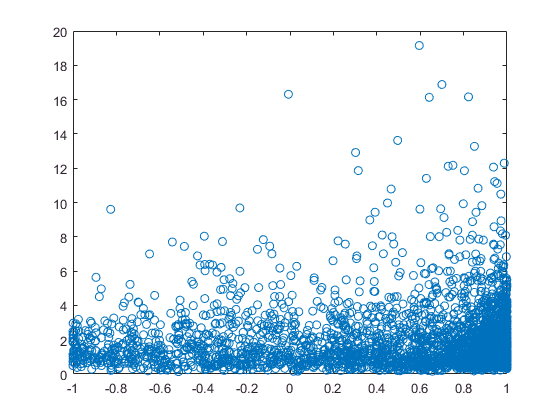

% this is the tuning length analysis
relative_moddepth = moddepth_fixed./moddepth_elast;
figure
plot(cosdPD,relative_moddepth,'o')

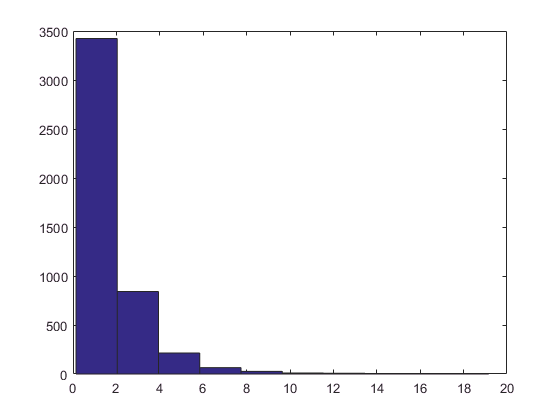

figure
hist(relative_moddepth)

disp(['Median relative moddepth: ' num2str(median(relative_moddepth))])

Median relative moddepth: 1.2793


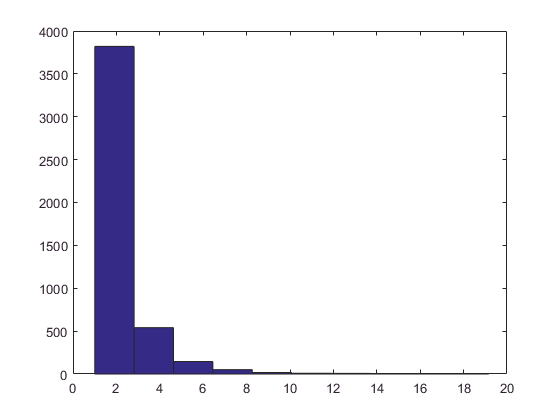


figure
hist(exp(abs(log(relative_moddepth))))

disp(['Median relative moddepth (exp abs log): ' num2str(median(exp(abs(log(relative_moddepth)))))])

Median relative moddepth (exp abs log): 1.5839


## Find neurons that look like endpoint but not joint

% ...somehow
figure
for i = 1:100
    clf
    subplot(4,3,2)
    plot(best_act_elast(i,:),best_act_fixed(i,:),'ko')
    axis equal
    hold on
    plot([0 60],[0 60],'k--')
    
    subplot(4,3,4)
    plot(joint_angles{1}(:,1),best_act_elast(i,:)','ko')
    subplot(4,3,5)
    plot(joint_angles{2}(:,1),best_act_fixed(i,:)','ko')
    subplot(4,3,6)
    plot(joint_angles{1}(:,1),joint_angles{2}(:,1),'ko')
    axis equal
    
    subplot(4,3,7)
    plot(joint_angles{1}(:,2),best_act_elast(i,:)','ko')
    subplot(4,3,8)
    plot(joint_angles{2}(:,2),best_act_fixed(i,:)','ko')
    subplot(4,3,9)
    plot(joint_angles{1}(:,2),joint_angles{2}(:,2),'ko')
    axis equal
    
    subplot(4,3,10)
    plot(joint_angles{1}(:,3),best_act_elast(i,:)','ko')
    subplot(4,3,11)
    plot(joint_angles{2}(:,3),best_act_fixed(i,:)','ko')
    subplot(4,3,12)
    plot(joint_angles{1}(:,3),joint_angles{2}(:,3),'ko')
    axis equal
    
    waitforbuttonpress
end

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted


clear i

## Joint elasticity sensitivity analysis

% load data
% load('elast_sensitivity_20161216.mat')

%% get minimal PD change values to compute numerical derivatives
% choices = [38 58 62 63 64 68 88]';
choices = [13 53 61 63 65 73 113]';
mini_pdChange_spring = pdChange_spring(choices)'

mini_pdChange_spring =    23.4566
   24.8752
   17.7110
   21.6330
   25.3362
   19.7079
   19.9786


mini_spring_list = spring_list(choices,:)

mini_spring_list =     0.7500    1.0000    1.0000
    1.0000    0.7500    1.0000
    1.0000    1.0000    0.7500
    1.0000    1.0000    1.0000
    1.0000    1.0000    1.2500
    1.0000    1.2500    1.0000
    1.2500    1.0000    1.0000


mini_num_tuned_spring = num_tuned_spring(choices)'

mini_num_tuned_spring =         4750
        4533
        4593
        4611
        4632
        4719
        4533



%% Calculate partial derivatives
hip_idx = [1;7];
knee_idx = [2;6];
ankle_idx = [3;5];

% hip
dChange_dHip = diff(mini_pdChange_spring(hip_idx))/diff(mini_spring_list(hip_idx,1));
dChange_dKnee = diff(mini_pdChange_spring(knee_idx))/diff(mini_spring_list(knee_idx,2));
dChange_dAnkle = diff(mini_pdChange_spring(ankle_idx))/diff(mini_spring_list(ankle_idx,3));


## Tuning weight analysis

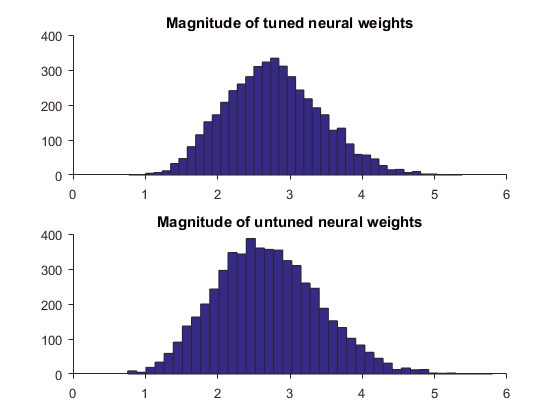

% find nullspace of muscle directions (elast)
% null_elast = null(muscle_coef_elast);
weight_mags = sqrt(sum(neurons.^2,2));
norm_weights = neurons./repmat(weight_mags,1,8);
figure
subplot(211)
hist(weight_mags(isTuned),40)
set(gca,'xlim',[0 6],'box','off','tickdir','out')
title 'Magnitude of tuned neural weights'
subplot(212)
hist(weight_mags(~isTuned),40)
set(gca,'xlim',[0 6],'box','off','tickdir','out')
title 'Magnitude of untuned neural weights'

med_weight_tuned = median(weight_mags(isTuned))

med_weight_tuned = 2.7490

med_weight_untuned = median(weight_mags(~isTuned))

med_weight_untuned = 2.6491

med_weight_ratio = (med_weight_tuned-med_weight_untuned)/med_weight_tuned

med_weight_ratio = 0.0363

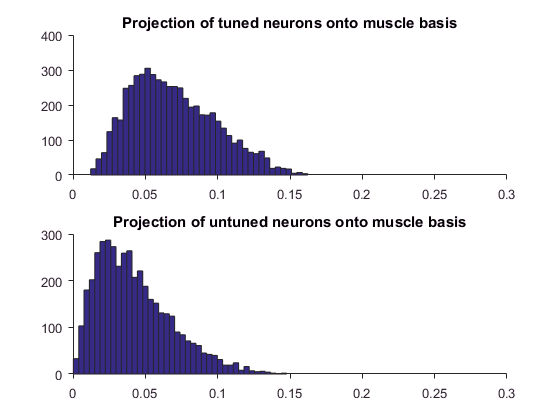


% find length of weighted vectors for tuned vs untuned neurons
neural_coefs = muscle_coef_elast*norm_weights';
neural_mags = sqrt(sum(neural_coefs.^2));
figure
subplot(211)
hist(neural_mags(:,is_best_elast'),40)
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
title 'Projection of tuned neurons onto muscle basis'
subplot(212)
hist(neural_mags(:,~is_best_elast'),40)
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
title 'Projection of untuned neurons onto muscle basis'

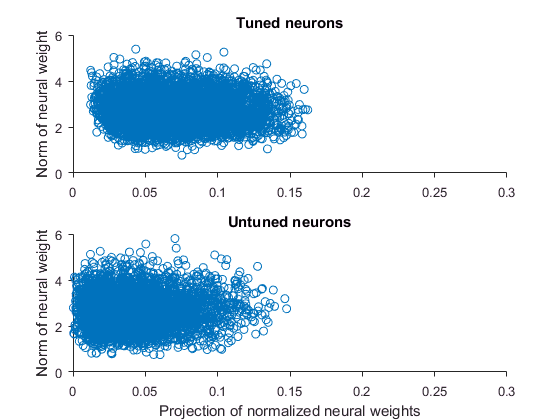


figure
subplot(211)
plot(neural_mags(:,is_best_elast'),weight_mags(is_best_elast),'o')
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
ylabel 'Norm of neural weight'
title 'Tuned neurons'
subplot(212)
plot(neural_mags(:,~is_best_elast'),weight_mags(~is_best_elast),'o')
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
title 'Untuned neurons'
ylabel 'Norm of neural weight'
xlabel 'Projection of normalized neural weights'




med_tuned_elast = median(neural_mags(:,is_best_elast'))

med_tuned_elast = 0.0654

med_untuned_elast = median(neural_mags(:,~is_best_elast'))

med_untuned_elast = 0.0378

ratio_elast = (med_tuned_elast-med_untuned_elast)/med_tuned_elast

ratio_elast = 0.4222

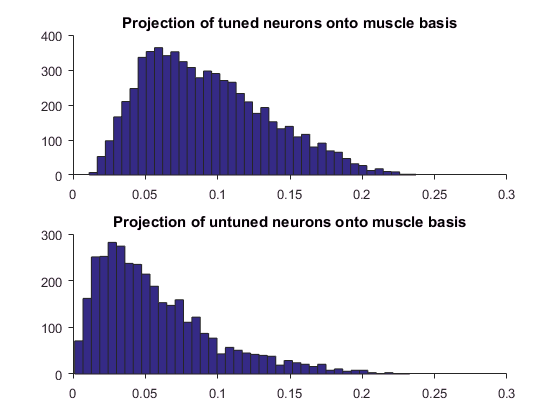


neural_coefs = muscle_coef_fixed*norm_weights';
neural_mags = sqrt(sum(neural_coefs.^2));
figure
subplot(211)
hist(neural_mags(:,is_best_fixed'),40)
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
title 'Projection of tuned neurons onto muscle basis'
subplot(212)
hist(neural_mags(:,~is_best_fixed'),40)
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
title 'Projection of untuned neurons onto muscle basis'

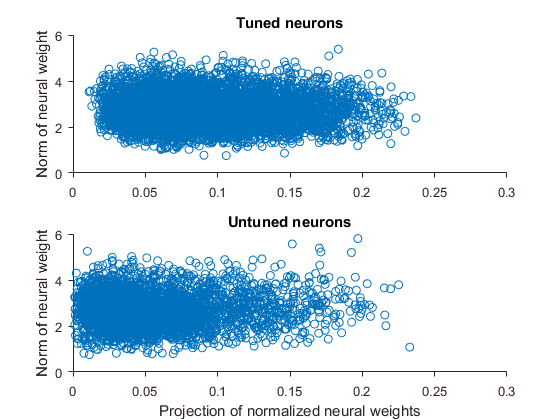

figure
subplot(211)
plot(neural_mags(:,is_best_fixed'),weight_mags(is_best_fixed),'o')
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
ylabel 'Norm of neural weight'
title 'Tuned neurons'
subplot(212)
plot(neural_mags(:,~is_best_fixed'),weight_mags(~is_best_fixed),'o')
set(gca,'xlim',[0 0.3],'box','off','tickdir','out')
title 'Untuned neurons'
ylabel 'Norm of neural weight'
xlabel 'Projection of normalized neural weights'


med_tuned_fixed = median(neural_mags(:,is_best_fixed'))

med_tuned_fixed = 0.0860

med_untuned_fixed = median(neural_mags(:,~is_best_fixed'))

med_untuned_fixed = 0.0472

ratio_fixed = (med_tuned_fixed-med_untuned_fixed)/med_tuned_fixed

ratio_fixed = 0.4506